# **Αναγνώριση προτύπων**

## Υπολογιστική εργασία 2021-2022

## Προσέγγιση τιμών ακινήτων με χρήση αλγορίθμων μηχανικής μάθησης

### **Μέλη ομάδας και ΑΜ**

- Νικήτας Χατζής Π19183

- Αντώνης Δαρμής Π19040

- Παναγιώτης Μουρλάς Π19108

### Requirements

- Statistics and Machine Learning Toolbox

- Deep Learning Toolbox

- Econometrics Toolbox (`corrplot`)

### **Περιεχόμενα**

ΦΟΡΤΩΣΗ ΤΩΝ ΔΕΔΟΜΕΝΩΝ

ΠΡΟΕΠΕΞΕΡΓΑΣΙΑ ΤΩΝ ΔΕΔΟΜΕΝΩΝ

    Διαχωρισμός αριθμητικών-κατηγορηματικών χαρακτηρηστικών

    Αντικατάσταση ελλειπών τιμών με διάμεση τιμή

    Κλιμάκωση των δεδομένων

    One Hot Vector encoding των κατηγορηματικών χαρακτηρηστικών

ΟΠΤΙΚΟΠΟΙΗΣΗ ΔΕΔΟΜΕΝΩΝ

    Ιστογράμματα

    Δισδιάστατα γραφήματα

        Scatter plots

        Correlations

ΠΑΛΙΝΔΡΟΜΗΣΗ ΔΕΔΟΜΕΝΩΝ

    Αλγόριθμος ελάχιστου μέσου τετραγωνικού σφάλματος

    Αλγόριθμος ελάχιστου τετραγωνικού σφάλματος

    Πολυστρωματικό νευρωνικό δίκτυο

### Α. Φόρτωση των δεδομένων

Η συνάρτηση `readtable` διαβάζει τα δεδομένα από το csv και τα αποθηκεύει ως table, μαζί με τα ονόματα των στηλών. Η συνάρτηση `movevars` απλώς μετακινεί η στήλη του χαρακτηρηστικού στόχου `median_house_value` στο τέλος του πίνακα, ώστε να την ξεχωρίσουμε πιο εύκολα παρακάτω.

data = readtable("housing.csv"); %read csv
data = movevars(data,"median_house_value",'After',"ocean_proximity");
fprintf('Data loaded.\n');

Data loaded.


Αφού διαβάσουμε τα δεδομένα ξεχωρίζουμε το χαρακτηρηστικό που θέλουμε να προσεγγίσουμε από τα υπόλοιπα. Στη μεταβλητή `y` αποθηκεύουμε τη στήλη με τις τιμές του χαρακτηρηστικού που μας ζητείται να προσεγγίσουμε, ενώ στη μεταβλητή `X` τις υπόλοιπες.

X = data(:,1:9);
y= data(:,"median_house_value");
fprintf('Table split to X and y complete.\n');

Table split to X and y complete.


### Β. Προεπεξεργασία των δεδομένων

#### 1) Αριθμητικά - κατηγορηματικά χαρακτηρηστικά

Κάνουμε print την πρώτη γραμμή των παραπάνω μεταβλητών ώστε να δούμε τι τιμές παίρνουν τα χαρακτηρηστικά.

X(1,:)

ans = 1×9 table
    longitude    latitude    housing_median_age    total_rooms    total_bedrooms    population    households    median_income    ocean_proximity
    _________    ________    __________________    ___________    ______________    __________    __________    _____________    _______________

     -122.23      37.88              41                880             129             322           126           8.3252         {'NEAR BAY'}  


y(1,:)

ans = table
    median_house_value
    __________________

        4.526e+05     


Και στη συνέχεια χρησιμοποιούμε την έτοιμη συνάρτηση `class` της matlab για να δούμε τον τύπο των δεδομένων κάθε στήλης

class(X.longitude)

ans = 'double'

class(X.latitude)

ans = 'double'

class(X.housing_median_age)

ans = 'double'

class(X.total_rooms)

ans = 'double'

class(X.total_bedrooms)

ans = 'double'

class(X.population)

ans = 'double'

class(X.households)

ans = 'double'

class(X.median_income)

ans = 'double'

class(X.ocean_proximity)

ans = 'cell'

class(y.median_house_value)

ans = 'double'

Βλέπουμε πως τα όλα τα χαρακτηρηστικά είναι αριθμητικά εκτός από το `ocean_proximity`**, **που είναι κατηγορηματικό. Χρησιμοποιώντας τη συνάρτηση `unique` μπορούμε να δούμε τις πιθανές τιμές του χαρακτηρηστικού αυτού.

ocean_proximity_values = unique(X.ocean_proximity) 

ocean_proximity_values = 5×1 cell array
    {'<1H OCEAN' }
    {'INLAND'    }
    {'ISLAND'    }
    {'NEAR BAY'  }
    {'NEAR OCEAN'}


#### 2) Imputing - εύρεση ελλειπών τιμών και αντικατάστασή τους με τη διάμεση τιμή

Βλέποντας τα ονόματα των στηλών του πίνακα και συνδυάζοντας τη συνάρτηση `sum` με τη συνάρτηση `ismissing` βλέπουμε πόσες τιμές λείπουν από κάθε χαρακτηρηστικό (η συνάρτηση `ismissing` επιστρέφει 1 αν λείπει η τιμή, αλλιώς 0 και έπειτα συνάρτηση `sum` αθροίζει αυτούς τους άσσους σε κάθε στήλη).

X.Properties.VariableNames

ans = 1×9 cell array
    {'longitude'}    {'latitude'}    {'housing_median_age'}    {'total_rooms'}    {'total_bedrooms'}    {'population'}    {'households'}    {'median_income'}    {'ocean_proximity'}


sum(ismissing(X))

ans =      0     0     0     0   207     0     0     0     0


 Λείπουν τιμές μόνο στο χαρακτηρηστικό `total_bedrooms`. Χρησιμοποιούμε τη συνάρτηση `median` με την παραμέτρους τη στήλη `total_bedrooms` και `'omitnan'` (για να αγνοηθούν οι τιμές που λείπουν στον υπολογισμό της διάμεσης τιμής). Στη συνέχεια γεμίζουμε τις κενές θέσεις της στήλης αυτής (τις βρίσκουμε με τη συνάρτηση `isnan`) με τη διάμεση τιμή που μόλις βρήκαμε και ξαναελέγχουμε για σιγουριά εάν υπάρχουν άλλες ελλιπείς τιμές.

total_bedrooms_median = median(X.total_bedrooms,'omitnan');
X.total_bedrooms(isnan(X.total_bedrooms)) = total_bedrooms_median;
sum(ismissing(X.total_bedrooms))

ans = 0

Πλέον δεν έχουμε άλλες ελλιπείς τιμές.

#### 3) Scaling δεδομένων

Στη συνέχεια θα κάνουμε κλιμάκωση των αριθμητικών χαρακτηρηστικών του Χ και του y, για να βρίσκονται όλα στην κλίμακα 0-1. Χρησιμοποιούμε τη συνάρτηση `normalize` με την έξτρα παράμετρο `'range'` (γίνεται scaling, όχι normalization)

X_numerical = X(:,1:8);
X_numerical_scaled = normalize(X_numerical,'range');

y_scaled = normalize(y,'range');

Αν συγκρίνουμε τώρα τα ιστογράμματα του `y` και του `y_scaled`, φαίνεται πως πράγματι οι τιμές του `y_scaled` βρίσκονται μεταξύ 0 και 1. Το ίδιο θα ισχυεί για τις τιμές των αριθμητικών χαρακτηρηστικών του `X` (`X_numerical_scaled`) 

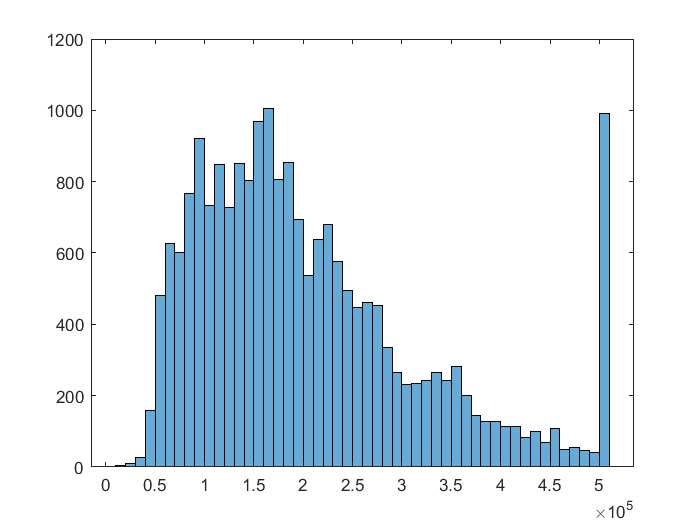

histogram(y.median_house_value(:,1))

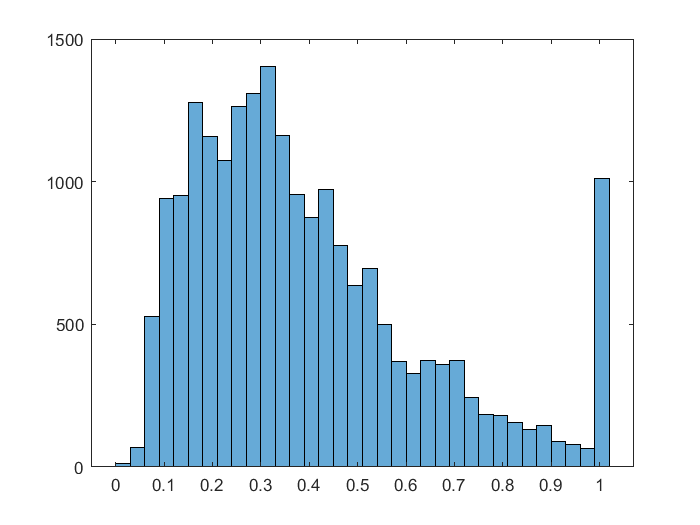

histogram(y_scaled.median_house_value(:,1))

#### 4) One hot vector encoding των κατηγορηματικών χαρακτηρηστικών

Παραπάνω βρήκαμε πως όλα τα χαρακτηρηστικά του `X` είναι αριθμητικά, εκτός από το `ocean_proximity`. Το ξεχωρίζουμε και εφαρμόζουμε One Hot Vector Encoding. Το OHVE είναι η αναπαράσταση κατηγορικών χαρακτηρηστικών ως δυαδικά διανύσματα.

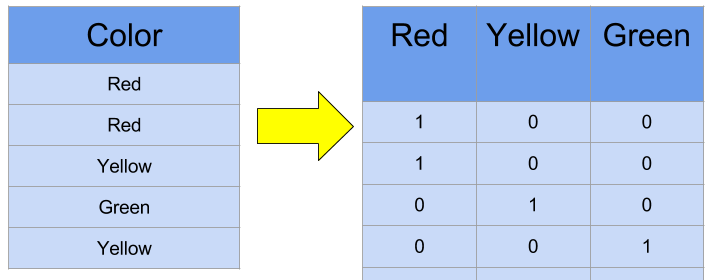

Ξεχωρίζουμε το κατηγορικό χαρακτηρηστικό και το μετατρέπουμε σε categorical array με τη συνάρτηση `categorical`. Στη συνέχεια χρησιμοποιούμε τη συνάρτηση `onehotencode` που πραγματοποιεί το OHVE.

X_categorical = X(:,9);
X_categorical.ocean_proximity = categorical(X_categorical.ocean_proximity);
X_categorical_encoded = onehotencode(X_categorical);

Και ελέγχουμε την πρώτη γραμμή για σιγουριά.

X_categorical_encoded(1,:)

ans = 1×5 table
    <1H OCEAN    INLAND    ISLAND    NEAR BAY    NEAR OCEAN
    _________    ______    ______    ________    __________

        0          0         0          1            0     


**Για την ώρα αποθηκεύουμε τα επεξεργασμένα δεδομένα σε ξέχωρες μεταβλητές. Μετά την οπτικοποίηση θα αντικατασταθούν οι αρχικές μορφές των **`X`** και **`y`** με τις νέες, επεξεργασμένες τιμές.**

### Γ. Οπτικοποίηση των δεδομένων

#### 1) Ιστογράμματα συχνοτήτων των χαρακτηρηστικών

Χρησιμοποιούμε τη συνάρτηση `histogram()` που μας παρέχει η matlab.

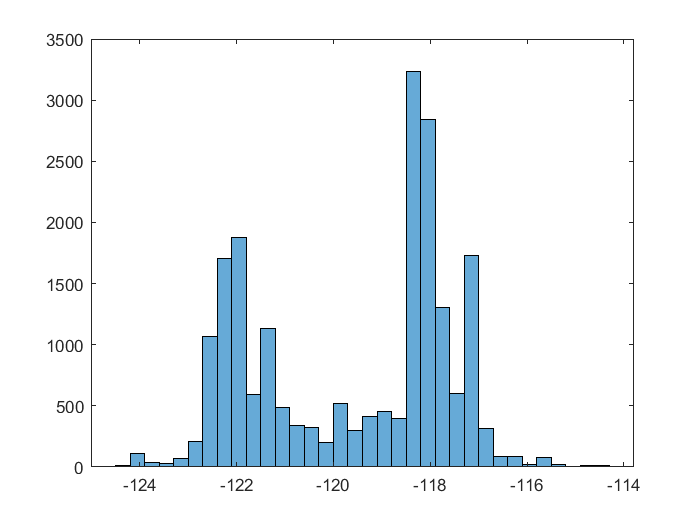

histogram(X.longitude);

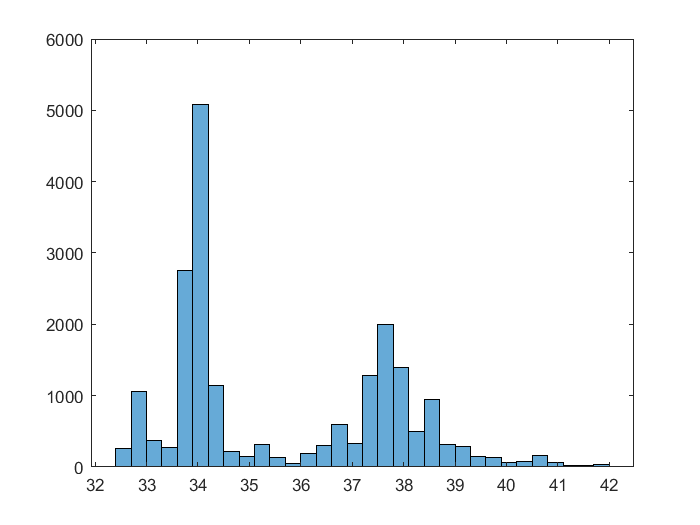

histogram(X.latitude);

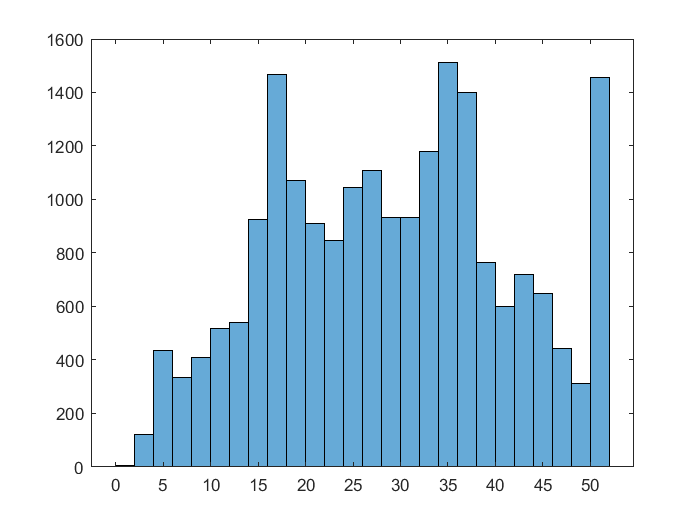

histogram(X.housing_median_age);

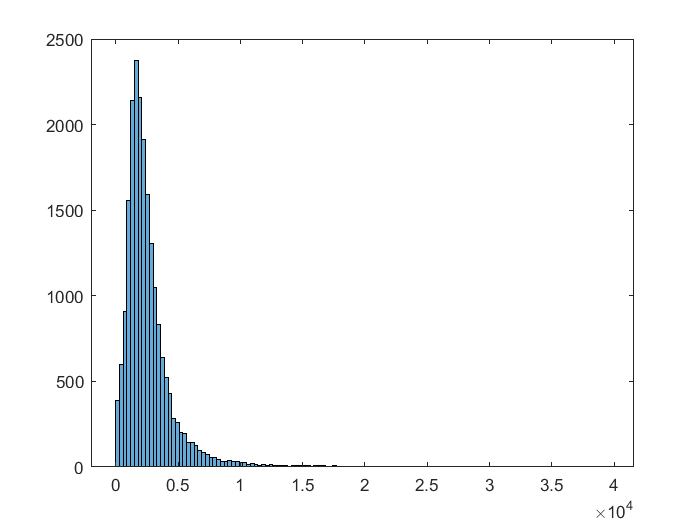

histogram(X.total_rooms);

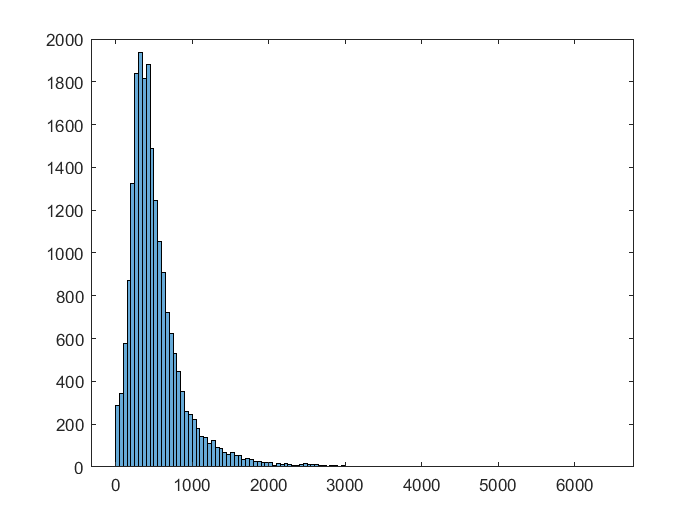

histogram(X.total_bedrooms);

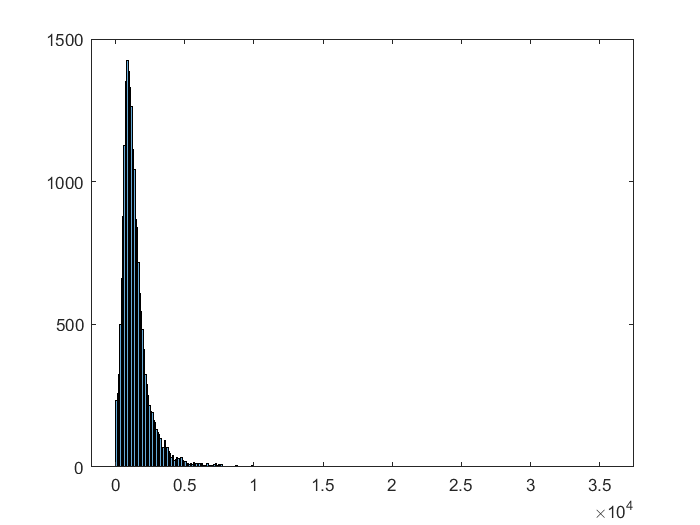

histogram(X.population);

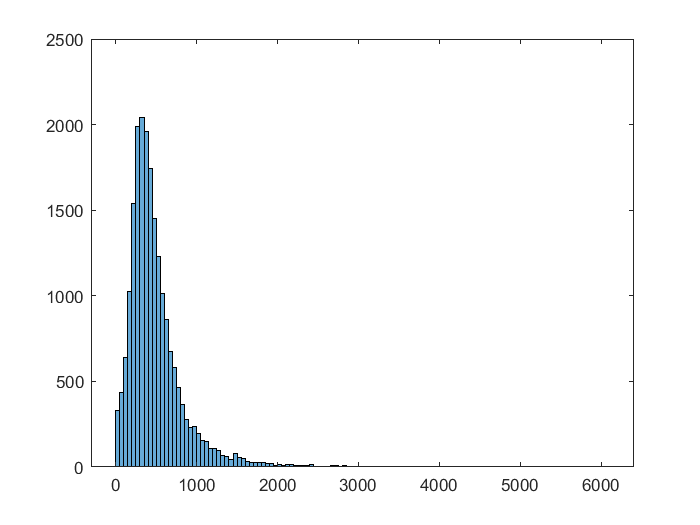

histogram(X.households);

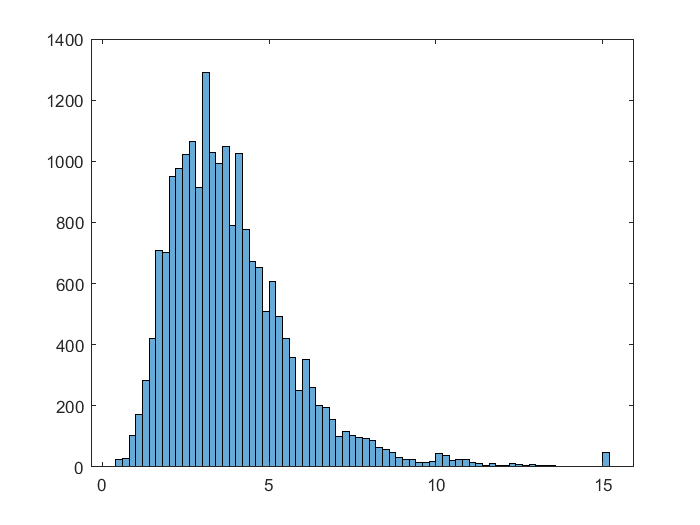

histogram(X.median_income);

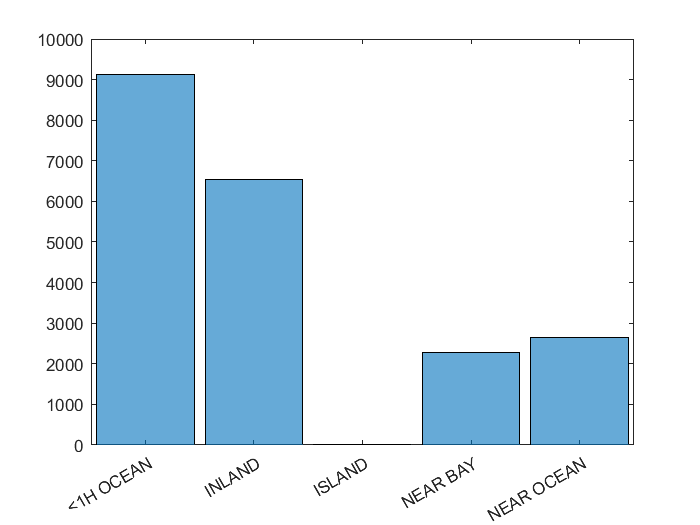

histogram(categorical(X.ocean_proximity));

histogram(y.median_house_value);

#### 2) Δισδιάστατα γραφήματα

Για αρχή θα χρησιμοποιήσουμε τη συνάρτηση `scatter` για να δούμε πως οι τιμές του χαρακτηρηστικού στόχου `median_house_value` διαμορφώνονται από τα υπόλοιπα χαρακτηρηστικά.

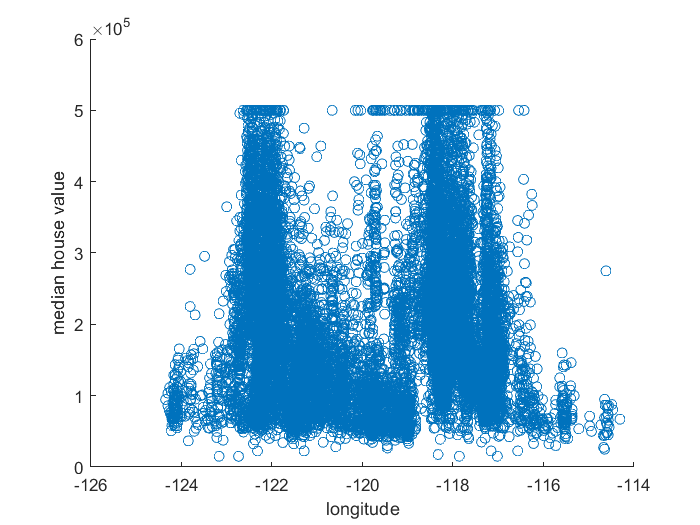

scatter(X.longitude,y.median_house_value);
xlabel('longitude');
ylabel('median house value');

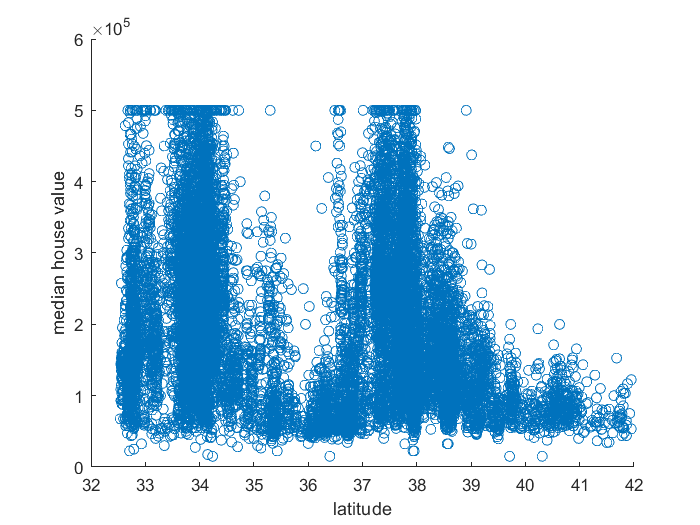


scatter(X.latitude,y.median_house_value);
xlabel('latitude');
ylabel('median house value');

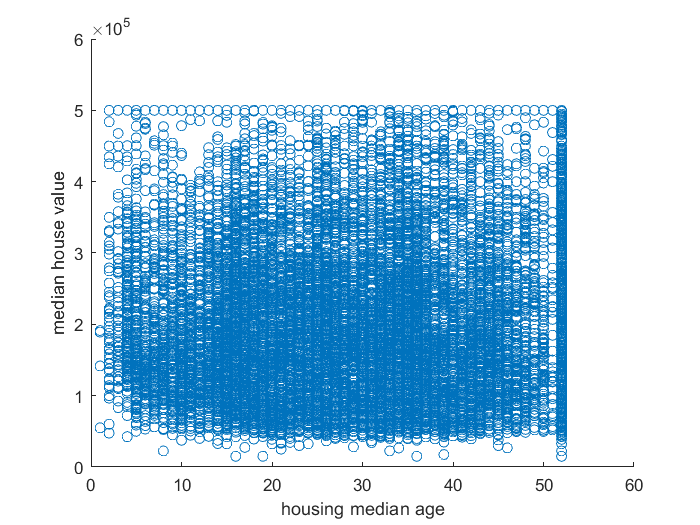


scatter(X.housing_median_age,y.median_house_value);
xlabel('housing median age');
ylabel('median house value');

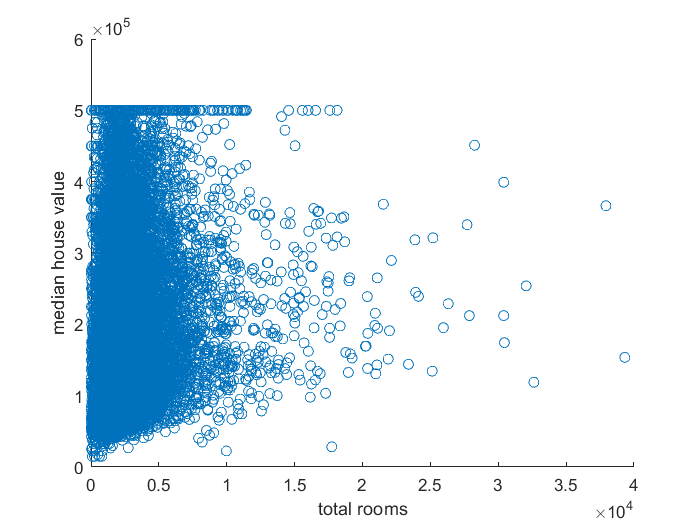


scatter(X.total_rooms,y.median_house_value);
xlabel('total rooms');
ylabel('median house value');

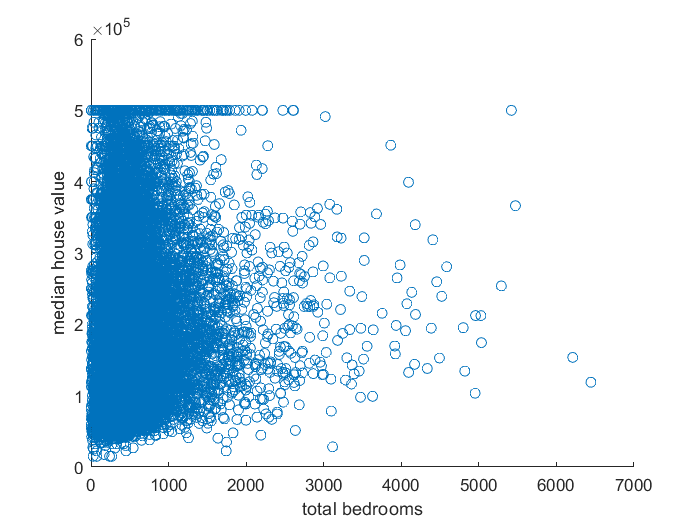


scatter(X.total_bedrooms,y.median_house_value);
xlabel('total bedrooms');
ylabel('median house value');

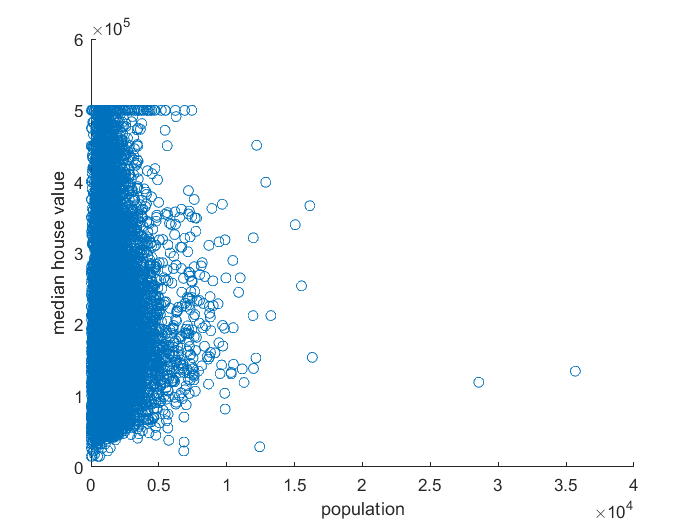


scatter(X.population,y.median_house_value);
xlabel('population');
ylabel('median house value');

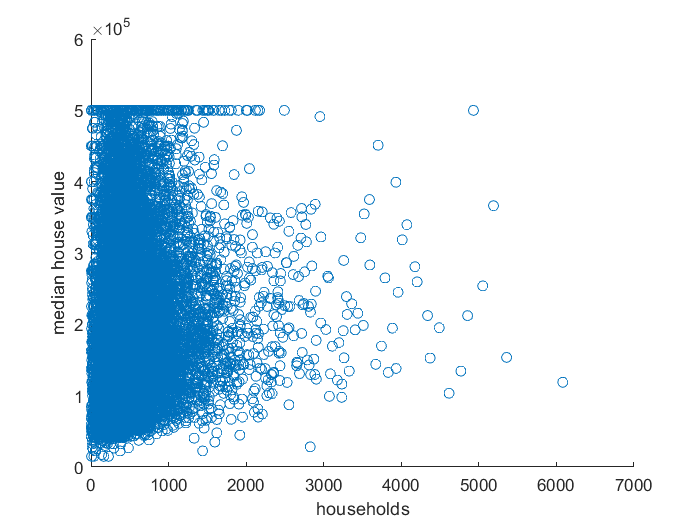


scatter(X.households,y.median_house_value);
xlabel('households');
ylabel('median house value');

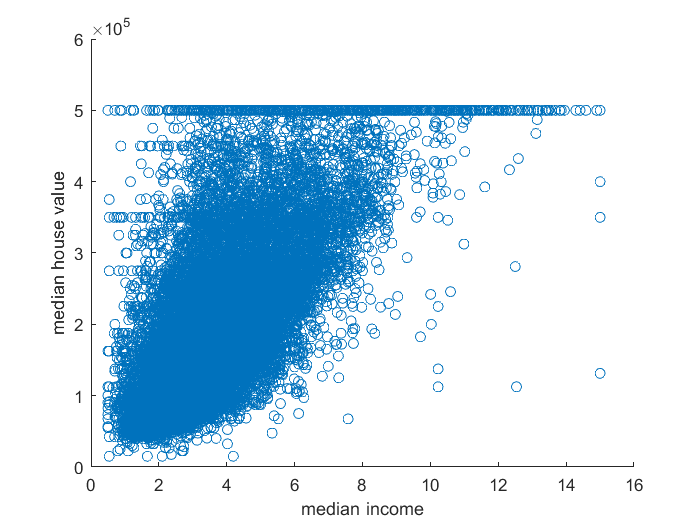


scatter(X.median_income,y.median_house_value);
xlabel('median income');
ylabel('median house value');

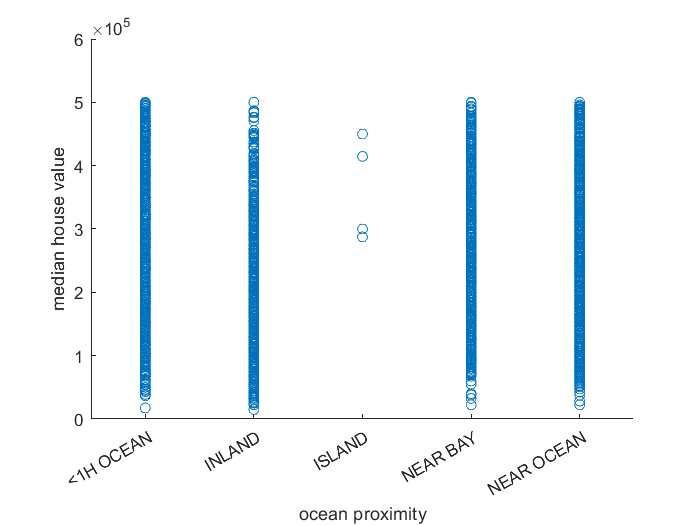


scatter(categorical(X.ocean_proximity),y.median_house_value);
xlabel('ocean proximity');
ylabel('median house value');

Βλέπουμε πως υπάρχει μια αρκετά γραμμική συσχέτιση μεταξύ του `median_income` και του `median_house_value`.

Αν σχεδιάσουμε τις συντεταγμένες βλέπουμε πως τα σπίτια μοιάζουν με την μορφή της πολιτείας. 

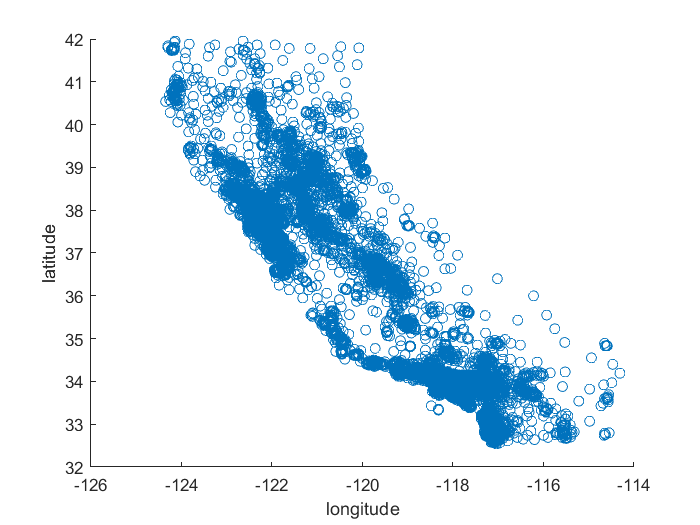

scatter(X.longitude,X.latitude);
xlabel('longitude');
ylabel('latitude');

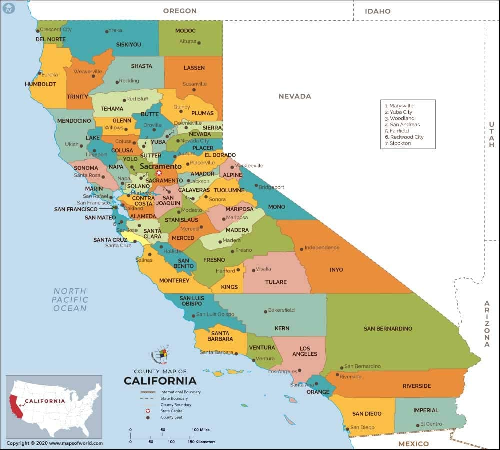

Αν προσθέσουμε χρώμα, τις τιμές και επαναλάβουμε, φαίνεται πως σε ορισμένες περιοχές η τιμή αυξάνεται όσο πλησιάζουμε τη θάλασα.

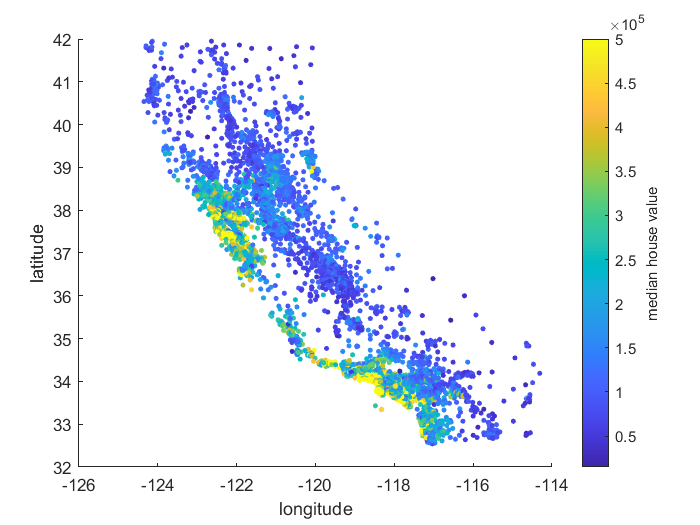

scatter(X.longitude,X.latitude,10,y.median_house_value,'filled');
xlabel('longitude');
ylabel('latitude');
a = colorbar;
a.Label.String = 'median house value';

**Pearson correlation**

Όσο πιο κοντά είναι η τιμή στο 1, τόσο πιο γραμμική είναι η σχέση μεταξύ των 2 χαρακτηρηστικών. Ελέγχουμε τη συσχέτιση όλων των χαρακτηρηστικών με το `median_house_value`. Χρησιμοποιούμε έτοιμη συνάρτηση του `Econometrics Toolbox corrplot` που υπολογίζει τον πίνακα $\rho _{XY}=\frac{cov(X,Y)}{\sigma _ X\sigma _Y}$ για κάθε συνδυασμό των $X$ και $Y$.

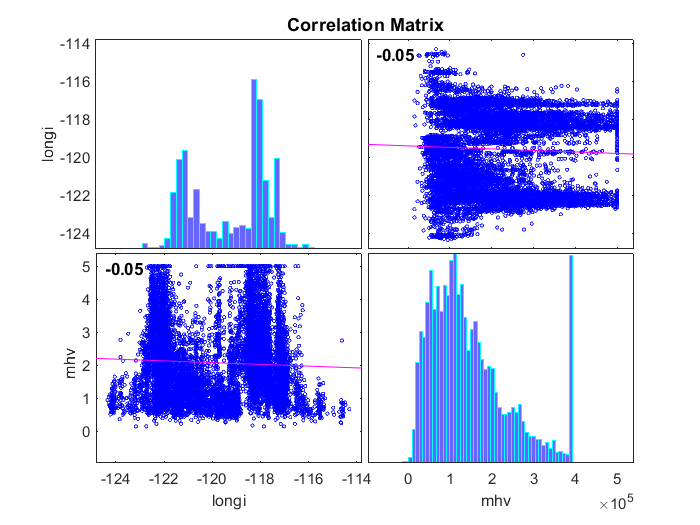

corrplot([X.longitude y.median_house_value],'varNames',{'longitude','mhv'});

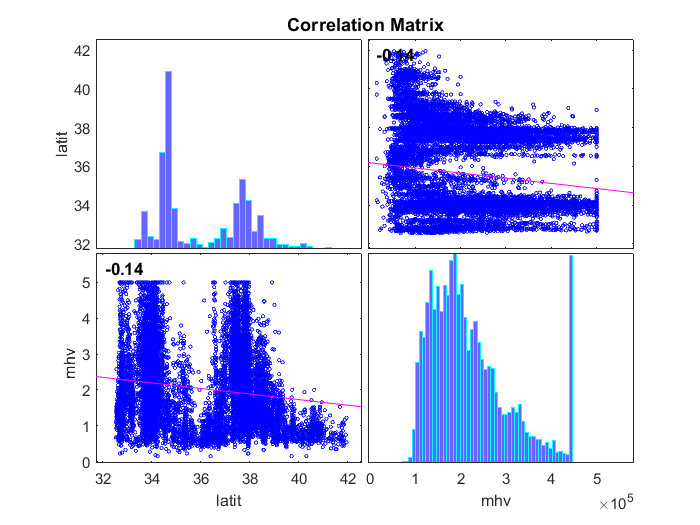

corrplot([X.latitude y.median_house_value],'varNames',{'latitude','mhv'});

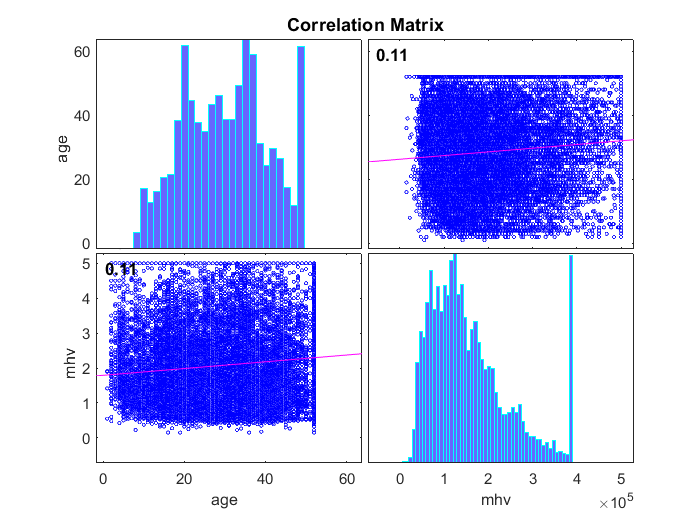

corrplot([X.housing_median_age y.median_house_value],'varNames',{'age','mhv'});

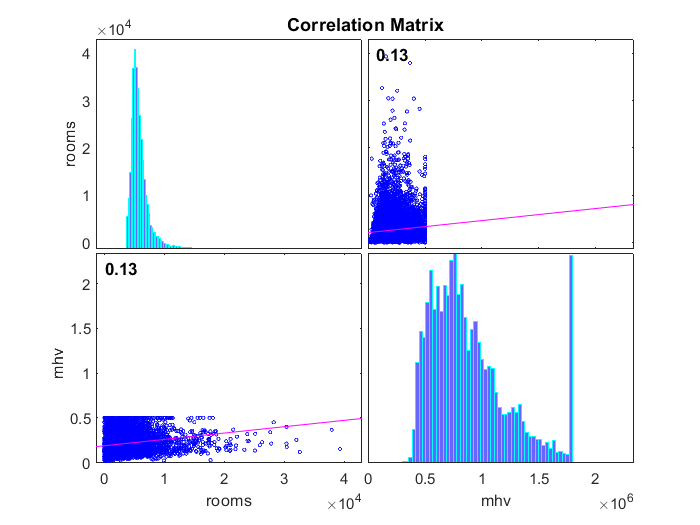

corrplot([X.total_rooms y.median_house_value],'varNames',{'rooms','mhv'});

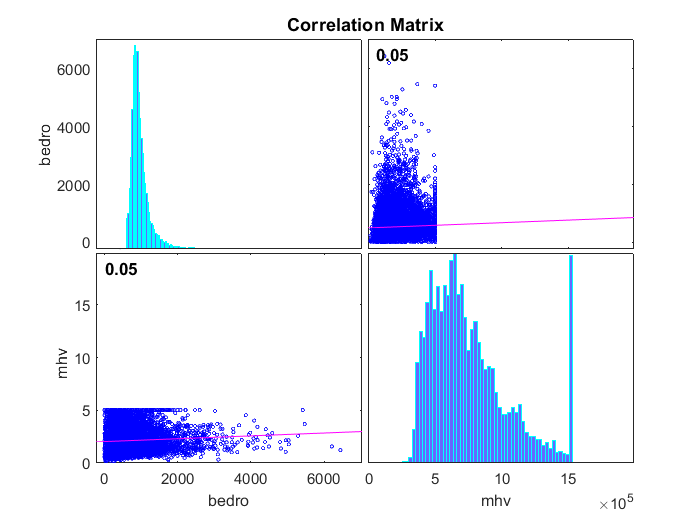

corrplot([X.total_bedrooms y.median_house_value],'varNames',{'bedrooms','mhv'});

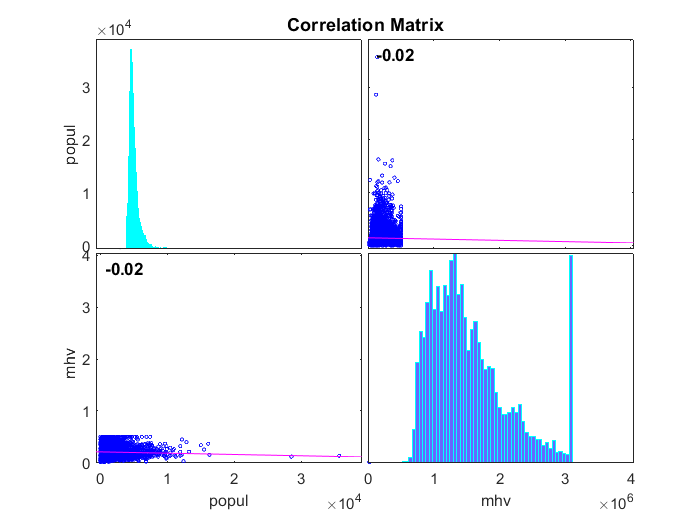

corrplot([X.population y.median_house_value],'varNames',{'population','mhv'});

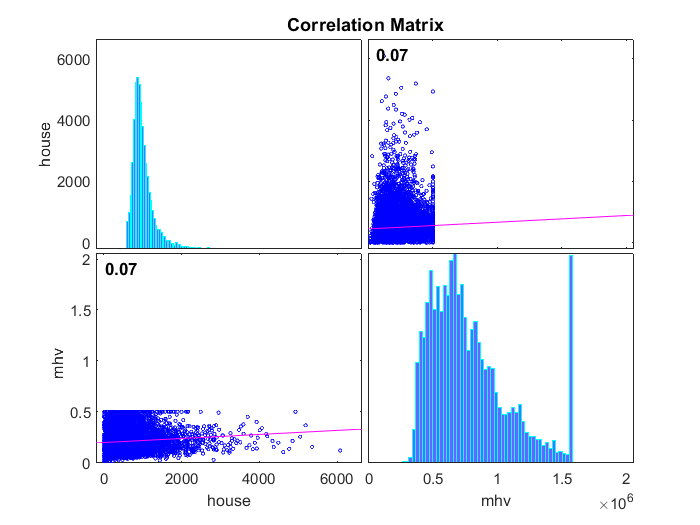

corrplot([X.households y.median_house_value],'varNames',{'households','mhv'});

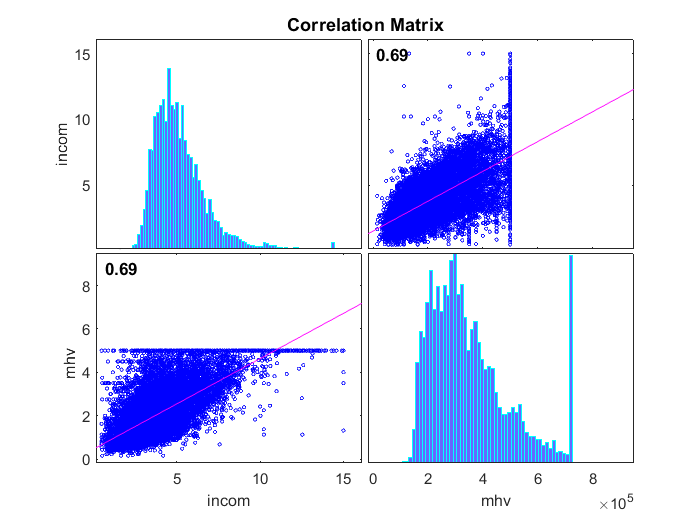

corrplot([X.median_income y.median_house_value],'varNames',{'income','mhv'});

Μεγαλύτερη τιμή έχει το `median_income`, κάτι που είχαμε υποψιαστεί προηγουμένως με τα scatterplots.

Δοκιμάζουμε και τις κατηγορικές στήλες

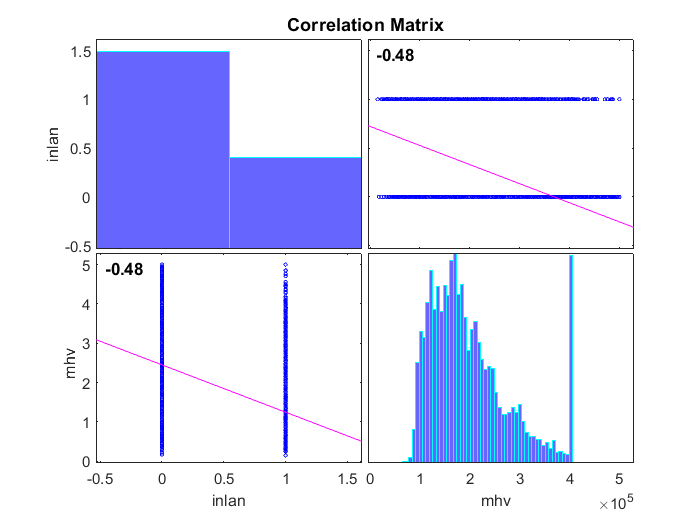

corrplot([X_categorical_encoded.INLAND y.median_house_value],'varNames',{'inland','mhv'});

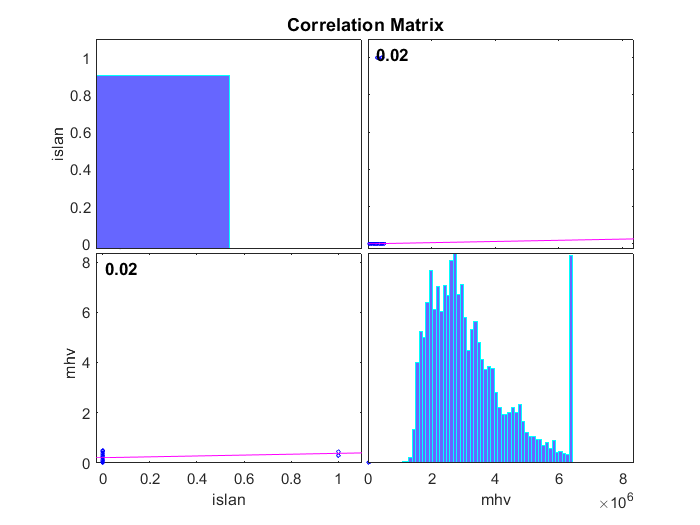

corrplot([X_categorical_encoded.ISLAND y.median_house_value],'varNames',{'island','mhv'});

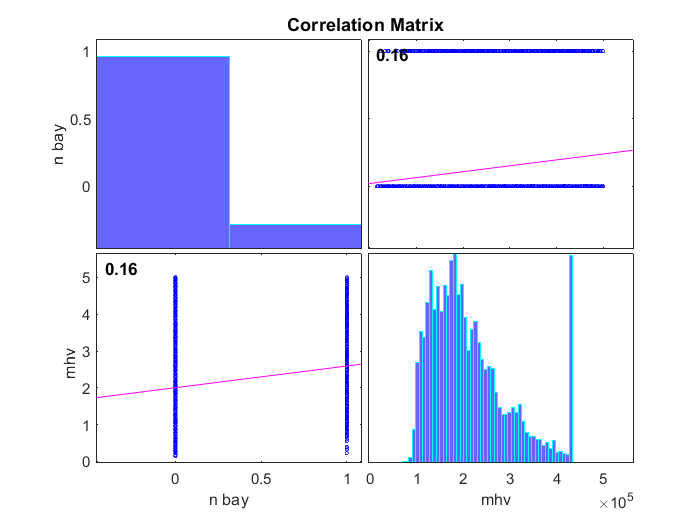

corrplot([X_categorical_encoded.("NEAR BAY") y.median_house_value],'varNames',{'n bay','mhv'});

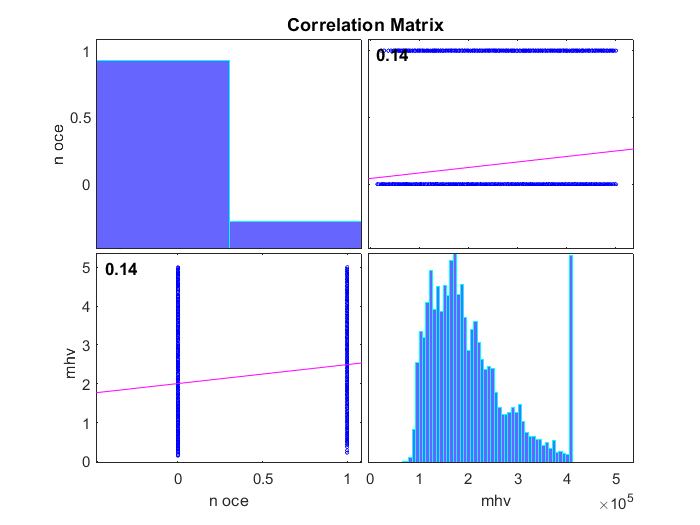

corrplot([X_categorical_encoded.("NEAR OCEAN") y.median_house_value],'varNames',{'n oce','mhv'});

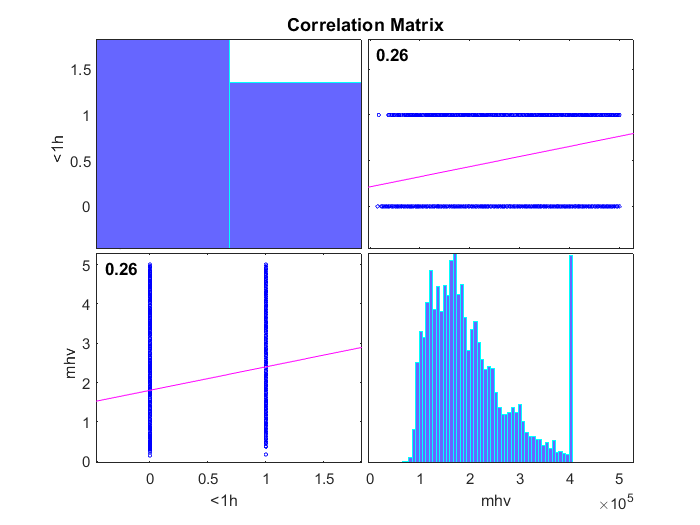

corrplot([X_categorical_encoded.("<1H OCEAN") y.median_house_value],'varNames',{'<1h','mhv'});

Υπάρχει κάποια ελάχιστη συσχέτιση με το χαρακτηρηστικό `ocean_proximity.('<1H OCEAN')`.

**Spearman rank correlation**

Όσο πλησιέστερη είναι η τιμή στο 1, τόσο καλύτερα μπορεί να περιγραφεί με μονότονη συνάρτηση η συσχέτιση μεταξύ των 2 χαρακτηρηστικών. Η τιμή υπολογίζεται από τη συνάρτηση `corr()`. Δοκιμάζουμε πάλι όλα τα χαρακτηρηστικά με το `median_house_value`.

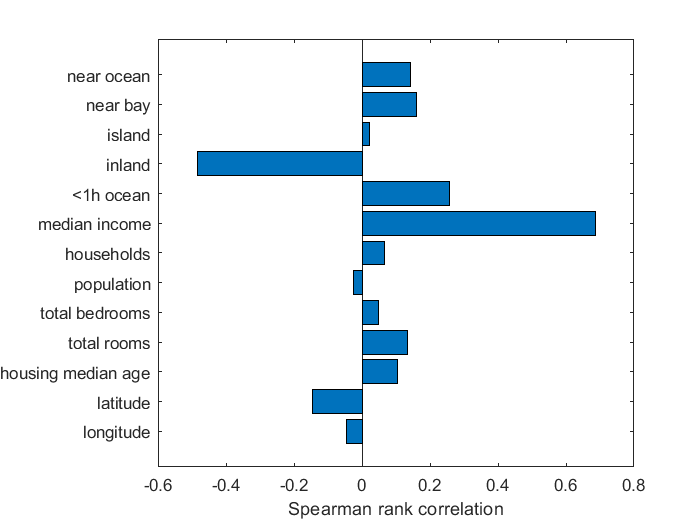

sr = zeros(1,13);
sr(1,1) = corr(X.longitude,y.median_house_value);
sr(1,2) = corr(X.latitude,y.median_house_value);
sr(1,3) = corr(X.housing_median_age,y.median_house_value);
sr(1,4) = corr(X.total_rooms,y.median_house_value);
sr(1,5) = corr(X.total_bedrooms,y.median_house_value);
sr(1,6) = corr(X.population,y.median_house_value);
sr(1,7) = corr(X.households,y.median_house_value);
sr(1,8) = corr(X.median_income,y.median_house_value);
sr(1,9) = corr(X_categorical_encoded.("<1H OCEAN"),y.median_house_value);
sr(1,10) = corr(X_categorical_encoded.("INLAND"),y.median_house_value);
sr(1,11) = corr(X_categorical_encoded.("ISLAND"),y.median_house_value);
sr(1,12) = corr(X_categorical_encoded.("NEAR BAY"),y.median_house_value);
sr(1,13) = corr(X_categorical_encoded.("NEAR OCEAN"),y.median_house_value);
barh(sr);
xlabel('Spearman rank correlation');
yticklabels({'longitude','latitude','housing median age', ...
    'total rooms','total bedrooms','population','households','median income', ...
    '<1h ocean', 'inland', 'island', 'near bay', 'near ocean'});

Όπως ήταν αναμενόμενο, η τιμή για το `median_income` είναι η μεγαλύτερη.

Παρόλο που δεν θα προσθέσουμε/αφαιρέσουμε χαρακτηρηστικά, ας δούμε και τη συσχέτιση όλων των χαρακτηρηστικών μεταξύ τους. Χρησιμοποιούμε πάλι τη συνάρτηση `corr` και την συνάρτηση `colormap`. 

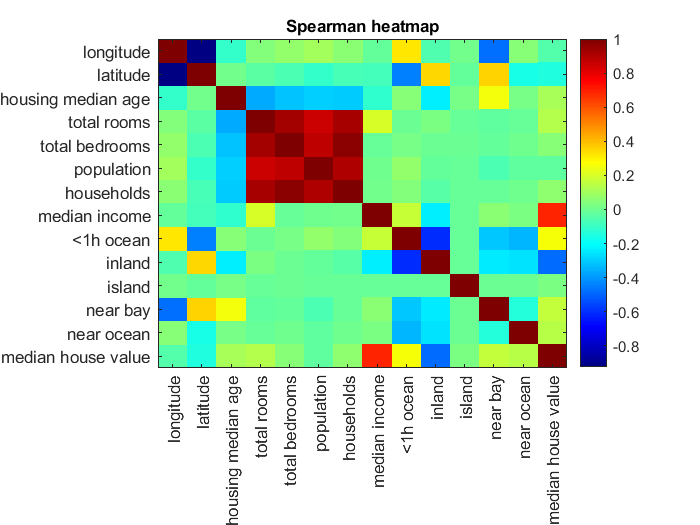

corr_table = corr(table2array([X_numerical X_categorical_encoded y]));
imagesc(corr_table);
set(gca, 'XTick', 1:14);
set(gca, 'YTick', 1:14);
set(gca, 'XTickLabel', {'longitude','latitude','housing median age', ...
    'total rooms','total bedrooms','population','households', ...
    'median income','<1h ocean', 'inland', 'island', 'near bay' ...
    , 'near ocean','median house value'});
set(gca, 'YTickLabel', {'longitude','latitude','housing median age', ...
    'total rooms','total bedrooms','population','households', ...
    'median income','<1h ocean', 'inland', 'island', 'near bay' ...
    , 'near ocean','median house value'});
title('Spearman heatmap', 'FontSize', 10);
xtickangle(90);
colormap('jet');
colorbar()

### Δ. Παλινδρόμηση των δεδομένων

Όπως επισημαίνεται και στην εκφώνηση της άσκησης χρησιμοποιούμε τη μέθοδο 10-fold cross validation

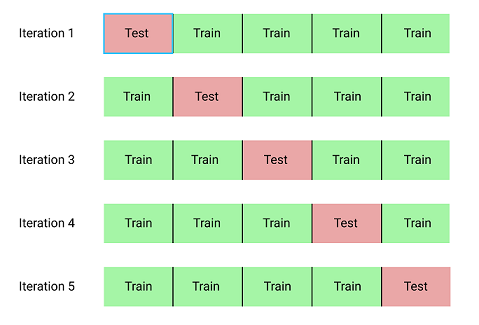

(στην περίπτωση μας έχουμε 10 iterations)

και για την μέτρηση της ακρίβειας χρησιμοποιούμε Μέσο Τετραγωνίκο Σφάλμα και Μέσο Απόλυτο Σφάλμα.

Το 10-fold υλοποιήθηκε με χρήση της συνάρτησης `cvpartition(sample_size,'KFold',folds)`, όπου στη περίπτωσή μας η παράμετρος `sample_size` αντιστοιχεί στον αριθμό γραμμών του `X` ή του `y` (βάλαμε το `y`) και η παράμετρος `folds` είναι 10 (αφού ζητείται 10-fold).

Για την ακρίβεια παλινδρόμησης χρησιμοποιήσαμε τις συναρτήσεις `mse(y1,y2)` και `mae(y1,y2)` όπου `y1` και `y2` οι πραγματικές και οι predicted τιμές αντίστοιχα για κάθε fold. 

#### 0) Μετασχηματισμοί δεδομένων

Τώρα που τελειώσαμε με την προεπεξεργασία και με την οπτικοποίηση, ενώνουμε τα `tables` με τα επεξεργασμένα χαρακτηρηστικά και τα αποθηκεύουμε στις αρχικές μεταβλητές `X` και `y`. Επίσης, μετατρέπουμε τις `X` και `y` σε πίνακες (από tables) με τη συνάρτηση `table2array`.

X = [X_numerical_scaled, X_categorical_encoded];
y = y_scaled;

X = table2array(X);
y = table2array(y);

#### 1) Αλγόριθμος Ελάχιστου Μέσου Τετραγωνικού Σφάλματος - Least Mean Squares

Ζητείται να ελαχιστοποιήσουμε μια συνάρτηση κόστους της μορφής:

$J(w )=\frac{1}{n}  \sum_{i=1}^{n} (y_i-X_i^Tw)^2 = E[|y- X^Tw|^2]$ (σελ.112 βιβλίου) με μέθοδο gradient descent που διατυπώνεται ως εξής:

$w_{t+1}=w_{t}-\rho  \frac{\theta J(w)}{\theta w}$ $\rightarrow$ $w_{t+1}=w_{t}-\frac{2\rho }{n}\sum_{i=1}^{n}X_i^T(y_i-X_i^Tw)$, όπου `n` ο αριθμός δειγμάτων.

Για το σκοπό αυτό υλοποιήσαμε τις συναρτήσεις `lms_cost` και `lms_descent, `που υπολογίζουν τη συνάρτηση κόστους $J(w)$ και το διάνυσμα βαρών $w_{t+1}$ αντίστοιχα. Η συνάρτηση `lms_descent(X,y,w,r,iter)` εκτός από τα δεδομένα `X` και `y`, παίρνει ως παραμέτρους το αρχικό διάνυσμα βαρών `w` (μηδενικά), `r` ο ρυθμός μάθησης και `iter` ο αριθμός επαναλήψεων. Ο αλγόριθμος σταματάει όταν γίνουν `iter` επαναλήψεις ή το κόστος συγκλίνει.

w = zeros(13,1);
iter = 1000;
ro = 0.1;

cv = cvpartition(height(y),'KFold',10);
for i=1:10
    X_train = X(cv.training(i),:);
    X_test = X(cv.test(i),:);
    
    y_train = y(cv.training(i),:);
    y_test = y(cv.test(i),:);
    
    w = lms_descent(X_train,y_train,w,ro,iter);
    
    pred = X_test*w;
    
    mserr = mse(pred,y_test);
    maerr = mae(pred,y_test);
    
    fprintf('Fold: %d\n',i);
    fprintf('MSE: %f\n', mserr);
    fprintf('MAE: %f\n', maerr);
end

Fold: 1


MSE: 0.146836


MAE: 0.309657


Fold: 2


MSE: 0.115602


MAE: 0.252508


Fold: 3


MSE: 0.089999


MAE: 0.215686


Fold: 4


MSE: 0.071926


MAE: 0.190278


Fold: 5


MSE: 0.067874


MAE: 0.180944


Fold: 6


MSE: 0.059703


MAE: 0.173211


Fold: 7


MSE: 0.058538


MAE: 0.173262


Fold: 8


MSE: 0.054371


MAE: 0.173641


Fold: 9


MSE: 0.049997


MAE: 0.162792


Fold: 10


MSE: 0.049162


MAE: 0.165666


#### 2) Αλγόριθμος Ελάχιστου Τετραγωνικού Σφάλματος - Least Squares

Πρόκειται για την γνωστή γραμμική παλινδρόμηση που γνωρίζουμε από τη στατιστική, για την οποία είναι γνωστό πως η συνάρτηση κόστους ελαχιστοποιείται όταν $w=(X^TX)^{-1}X^Ty$ (προκύπτει εφαρμόζωντας τη μέθοδο ελαχίστων τετραγώνων). Βρίσκεται επίσης στη σελίδα 118 του βιβλίου του μαθήματος.

Για το σκοπό αυτό, υλοποιήσαμε τη συνάρτηση `least_squares` που υπολογίζει το διάνυσμα βαρών.

Όπως και πριν, θα χρησιμοποιήσουμε 10-fold cross-validation στη διαδικασία της εκπαίδευσης και για την μέτρηση της ακρίβειας χρησιμοποιούμε Μέσο Τετραγωνίκο Σφάλμα και Μέσο Απόλυτο Σφάλμα.

for i=1:10
    X_train = X(cv.training(i),:);
    X_test = X(cv.test(i),:);
    
    y_train = y(cv.training(i),:);
    y_test = y(cv.test(i),:);
    
    w2 = least_squares(X_train,y_train);
    pred = X_test*w2;
    
    mserr = mse(pred,y_test);
    maerr = mae(pred,y_test);
    
    fprintf('Fold: %d\n',i);
    fprintf('MSE: %f\n', mserr);
    fprintf('MAE: %f\n', maerr);
end

Fold: 1


MSE: 0.020244


MAE: 0.104088


Fold: 2


MSE: 0.023181


MAE: 0.104362


Fold: 3


MSE: 0.019637


MAE: 0.102153


Fold: 4


MSE: 0.018543


MAE: 0.100790


Fold: 5


MSE: 0.020560


MAE: 0.104455


Fold: 6


MSE: 0.019426


MAE: 0.101195


Fold: 7


MSE: 0.021285


MAE: 0.104923


Fold: 8


MSE: 0.019125


MAE: 0.102179


Fold: 9


MSE: 0.020146


MAE: 0.100868


Fold: 10


MSE: 0.019400


MAE: 0.103490


#### 3) Πολυστρωματικό Νευρωνικό Δίκτυο - Multilayer Neural Network

Όπως και πριν, θα χρησιμοποιήσουμε 10-fold cross-validation στη διαδικασία της εκπαίδευσης και για την μέτρηση της ακρίβειας χρησιμοποιούμε Μέσο Τετραγωνίκο Σφάλμα και Μέσο Απόλυτο Σφάλμα. Κατασκευάζουμε το νευρωνικό δίκτυο με τη συνάρτηση `fitnet`, που ως παραμέτρους παίρνει τα μεγέθη των hidden layers (βάζουμε 2 hidden layers με μέγεθος 21 το κάθε ένα). Θέτουμε την παράμετρο `trainParam.showWindow` σε `false` για να μην εμφανίζεται το γραφικό περιβάλλον εκπαίδευσης σε κάθε επανάληψη. Στη συνέχεια κάνουμε train με τη συνάρτηση `train` και predict με τη συνάρτηση `net`.

Η αρχιτεκτονική του δικτύου μας είναι η εξής:

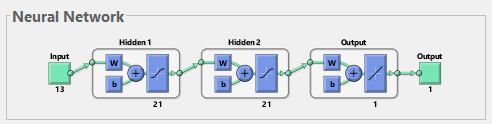

for i=1:10
    X_train = X(cv.training(i),:);
    X_test = X(cv.test(i),:);
    
    y_train = y(cv.training(i),:);
    y_test = y(cv.test(i),:);
    
    net = fitnet([21 21]);
    net.trainParam.showWindow = 0;
    %net.trainParam.epochs=10;
    net = train(net,X_train',y_train');
    
    pred = net(X_test');
    
    mserr = mse(pred',y_test);
    maerr = mae(pred',y_test);
    
    fprintf('Fold: %d\n',i);
    fprintf('MSE: %f\n', mserr);
    fprintf('MAE: %f\n', maerr);
end

Fold: 1


MSE: 0.012097


MAE: 0.073480


Fold: 2


MSE: 0.014743


MAE: 0.075342


Fold: 3


MSE: 0.011167


MAE: 0.070580


Fold: 4


MSE: 0.010163


MAE: 0.070763


Fold: 5


MSE: 0.013560


MAE: 0.073693


Fold: 6


MSE: 0.011802


MAE: 0.073440


Fold: 7


MSE: 0.012979


MAE: 0.077558


Fold: 8


MSE: 0.010768


MAE: 0.069677


Fold: 9


MSE: 0.013162


MAE: 0.072974


Fold: 10


MSE: 0.012033


MAE: 0.072532


### **Πηγές**

- **Αναγνώριση Προτύπων**, Σ. Θεοδωρίδης, Κ. Κουτρούμπας

- Σημειώσεις Αναγνώρισης προτύπων (gunet)

- Σημειώσεις Εφαρμοσμένης άλγεβρας (gunet)

- Σημειώσεις Πιθανοτήτων και στατιστικής (gunet)

- [https://www.kaggle.com/dgawlik/house-prices-eda](https://www.kaggle.com/dgawlik/house-prices-eda)

- [https://en.wikipedia.org/wiki/Pearson_correlation_coefficient](https://en.wikipedia.org/wiki/Pearson_correlation_coefficient)

- [https://en.wikipedia.org/wiki/Spearman%27s_rank_correlation_coefficient](https://en.wikipedia.org/wiki/Spearman%27s_rank_correlation_coefficient)

- matlab documentation